# APT 3D reconstruction

First, load in a dataset for reconstruction. This needs to contain the detector x and y coordinates as well as a way to identify individual ions for their respective volume. Also load all auxilliary information such as a color scheme and an isotopic table. The isotopic table contains the information about the volume occupied by each ion.

load('isotopeTable_naturalAbundances.mat');
load('colorScheme.mat');

% picking epos file
[file, path] = uigetfile('*.epos');
pos = posToTable([path file]);

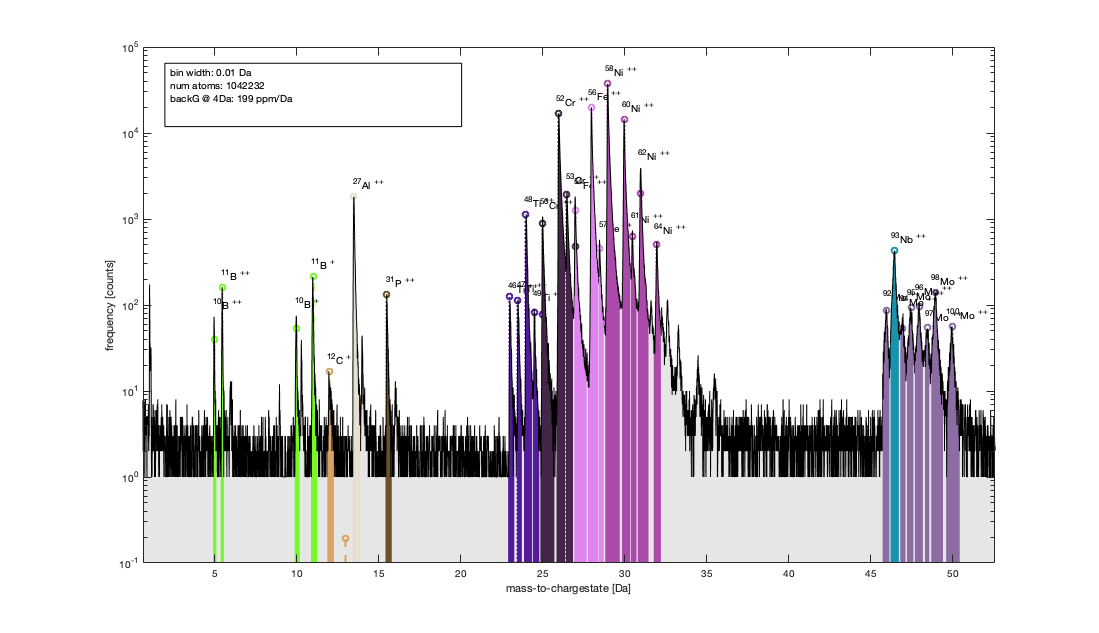


% picking ranges
[file, path] = uigetfile('*.fig');
rngFig = openfig([path file],'visible');

spec = findobj(rngFig,'DisplayName','mass spectrum');

% allocation of ranges
pos = posAllocateRange(pos,rangesExtractFromMassSpec(spec),'raw');
% calculation of ion volumes based on atomic densities of the elements
[ionVolumes, pos] = ionVolumesFromAtomVolumes(pos,isotopeTable);

## Reflectron image transformation

for reflectron instruments, a correction of the atomic hit coordinates must be carried out in order to account for the imaging properties of the reflectron. This transforms the detector hit coordinates onto a 'virtual detector', located 5.5 mm behind the specimen. The calibration file is specific to an instrument or instrument series.

load('LEAP4000XHR_calibrationGrid.mat');
pos = reflectronImageTransform(pos, intersections);

## Straight flight path image compression correction

In most straight flight path instruments, the detector sits at an electrostatic potential that is different than its surrounding. This leads to changing image compression as the specimen voltage changes. We can correct for this by using a master curve relative to a reference potential. 

## Creating a detector hull

In order to have a measurement of the effective detector area that ions impact on and to determine the boundary of the dataset, we can create a hull for the dataset in detector space. This hull is then co-reconstructed with the rest of the data.

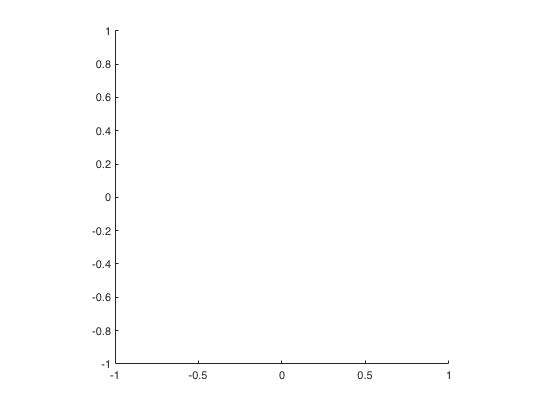

alphaRadius = 10; % alpha radius for each detector segment in the hit sequence
approxNumAtomPerSegment = 1E6; % approximate number of atoms per segment of the hull
numSeg = round(height(pos)/approxNumAtomPerSegment); % number of detector segments in the hit sequence. Here: about every 1M atoms
nGon = 32; % number of boundary vertices in each detector segment
capLoops = 4; % number of edge loops on top and bottom caps
useVoronoiFilter = false; % if detector is unfilled, filter stray 'ghost' hits. Can take a while.
filterNoiseLimit = 0.05; % fraction of hits with large Voronoi areas that define filter threshold.

[hullDetector, Area] = detectorHull(pos, alphaRadius, numSeg, nGon, capLoops, useVoronoiFilter, filterNoiseLimit);

## Reconstruction setup

instrument / experiment parameters

effectiveDetectorArea = 5^2*pi()/4; % area of the detector that is used in mm2
detectorEfficiency = .37; % fraction of atoms captured by the detector
flightPathLength = 5.5; % either physical or virtual
imageCompressionFactor = 1.2; % factor the image on the detector is smaller than if it would be if the ions flew in a straight line
ionVolume = pos.ionVolume; %ones([height(pos) 1]) * 70; % volume each ion takes up in the material
species = {'Al'}; % species used for visualisatoin of the reconstruction result

Calculation of radius evolution

kf = 3.3; % field factor. Proportionality between the field of a charged sphere and that of a real specimen.
Fevap = 19; % evaporation field. Critical field above which field evaporation takes place.
radius = pos.VDC ./ kf ./ Fevap; % resulting estimate of the radius evolution of the specimen

## Reconstruction

[pos, hullR] = posReconstruct3DGeiser(...
    pos,flightPathLength,detectorEfficiency,effectiveDetectorArea,ionVolume,radius,imageCompressionFactor,hullDetector);

## Visualisation of reconstruction results

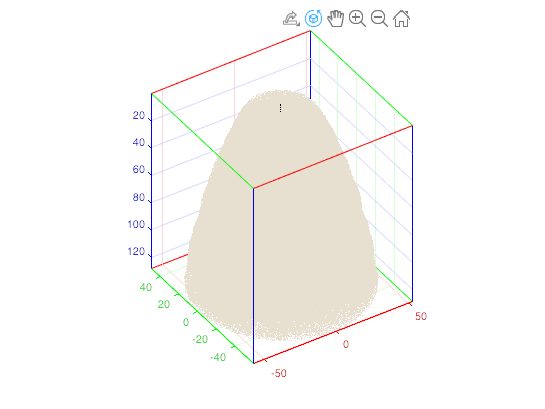

scatterPlotPosData(pos,species,1,colorScheme);
hold on;
patch(hullR(1),'FaceColor',[0 0 1],'FaceAlpha',0.1); % hull mantle
patch(hullR(2),'FaceColor',[0 0 1],'FaceAlpha',0.1); % hull top cap
patch(hullR(3),'FaceColor',[0 0 1],'FaceAlpha',0.1); % hull bottom cap

## Inverse reconstruction (deconstruction)

In order to optimise reconstructions, we may outline objects in inperfect reconstructions as use them to guide subsequent reconstruction optimisations. To this end, we can use a barycentric transformation to transform object vertex coordinates from reconstruction space to detector space. 

IMPORTANT: downsampling should be used for the pos and detector coordinated, as large datasets lead to excessive memory use and compute times. Downsampled dataset sizes of 10^5 - 10^6 are reasonable on a machine with 16GB RAM.

numSampledAtoms = 1E5;
sample = sort(randsample(height(pos),numSampledAtoms));
fvDetector = fv;
fvDetector.vertices = reconstructionToDetectorCoordinates(fv.vertices,pos(sample,:));

visualisation of object in detector coordinates

patch(hullR(1),'FaceColor',[0 0 1],'FaceAlpha',0); % hull mantle
patch(hullR(2),'FaceColor',[0 0 1],'FaceAlpha',0); % hull top cap
patch(hullR(3),'FaceColor',[0 0 1],'FaceAlpha',0); % hull bottom cap
patch(fvDetector,'FaceColor',[0 1 1],'FaceAlpha',1); % hull bottom cap